## 信号

clc;clear;close all;

定义一些函数

%定义宽带模糊函数
function [out, r_axis,v_axis] = widebandAF(x,fs,t,vel,c)

    pad_len=length(x)/2;
    signal = [zeros(1,pad_len),x,zeros(1,pad_len)];
    conj_rev_signal = conj(signal(end:-1:1));%共轭之后，再翻转


    time = linspace(-t(end),t(end),length(signal));
    delay = linspace(2 * time(1), 2 * time(end), 2 * length(signal) - 1);

    alpha = (c+vel)./(c-vel);
    %alpha = linspace(0.8, 1 / 0.8, 512);
    out = zeros(length(alpha), 2 * length(signal) - 1);

    for i = 1:length(alpha)
        out(i, :) = conv(signal, interp1(time, conj_rev_signal, time * alpha(i), 'spline'));
    end


    r_axis = c*delay/4;
    v_axis = vel;

end

## HFM信号

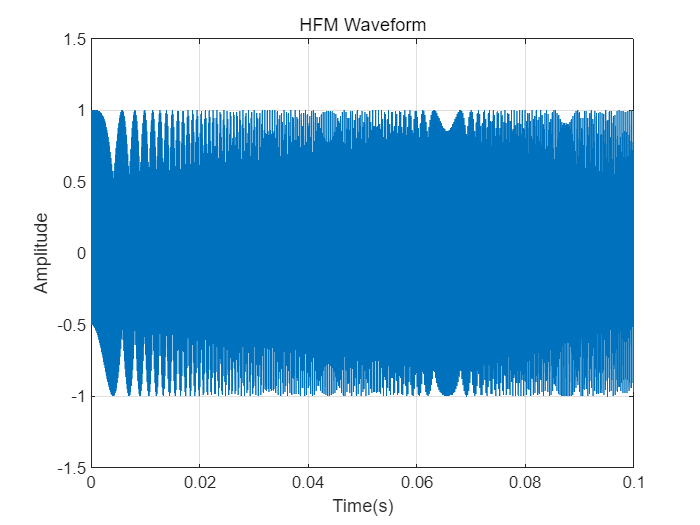

fs = 24e3;
T    = 0.1;         % 脉冲时长
t_hfm = 0.5/fs : 1/fs : T-0.5/fs;
t = 0:1/fs:T-1/fs;

fmin = 7e3;     % 起始频率
fmax = 9e3;     % 终止频率
A    = 1;         % 振幅

%% 生成 HFM
[t_hfm, pulse_HFM] = hfm_waveform(fs, T, fmin, fmax, A);

figure;
plot(t,real(pulse_HFM));xlabel('Time(s)');ylabel('Amplitude');
title('HFM Waveform');ylim([-1.5,1.5]);grid on;

时频谱

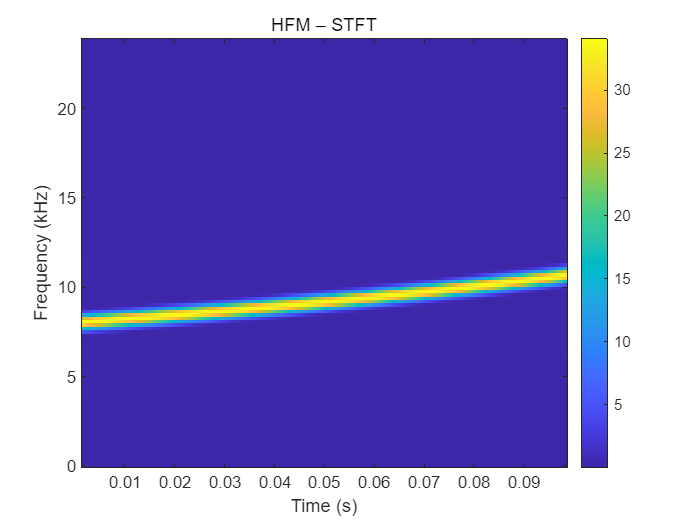

%% STFT
wlen   = 64;
nover  = 64-4;
nfft   = 128;
[STFT,F,Tstft] = spectrogram(pulse_HFM,wlen,nover,nfft,fs,'yaxis');

%% 绘图
figure;
imagesc(Tstft, F/1e3, abs(STFT));
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('HFM – STFT');

colorbar;

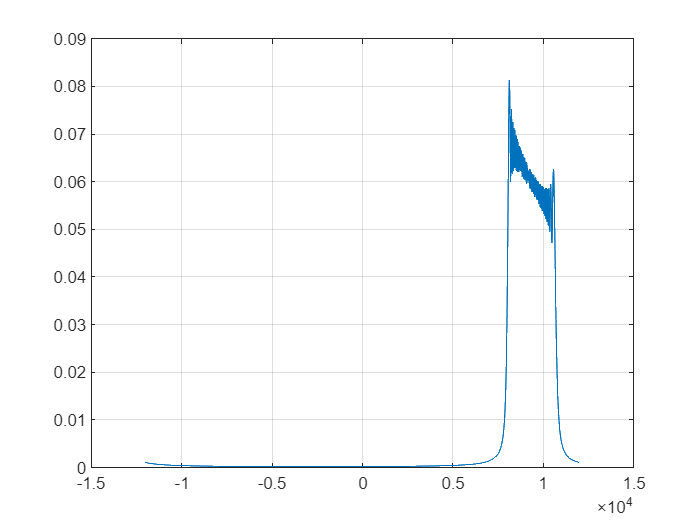

%计算中心频率
N_fft = length(pulse_HFM);
spec_hfm = fftshift(fft(pulse_HFM,N_fft))./N_fft;
f = -fs/2:fs/N_fft:fs/2 -fs/N_fft;
plot(f,abs(spec_hfm));grid on;

HFM宽带模糊函数

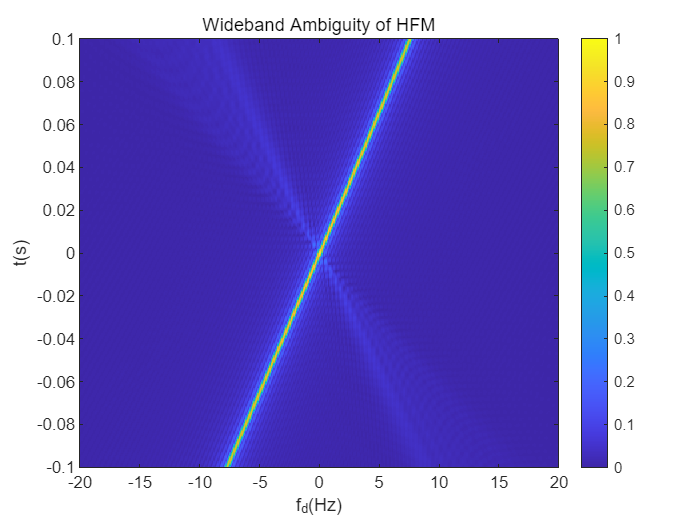

c=1500;
vel=-20:0.05:20;
[AF, r_axis,v_axis] = widebandAF(pulse_HFM.',fs,t,vel,c);%输入信号必须为行向量


fc = 12.5e3;
fd = v_axis./c*fc;
t = r_axis./(c/2);
%归一化
AF_norm = abs(AF)./max(max(abs(AF)));

imagesc(fd, t, AF_norm);
xlabel('f_d(Hz)');
ylabel('t(s)');
title('Wideband Ambiguity of HFM');
axis xy tight;
colorbar;
xlim([-20,20]);

HFM Q函数

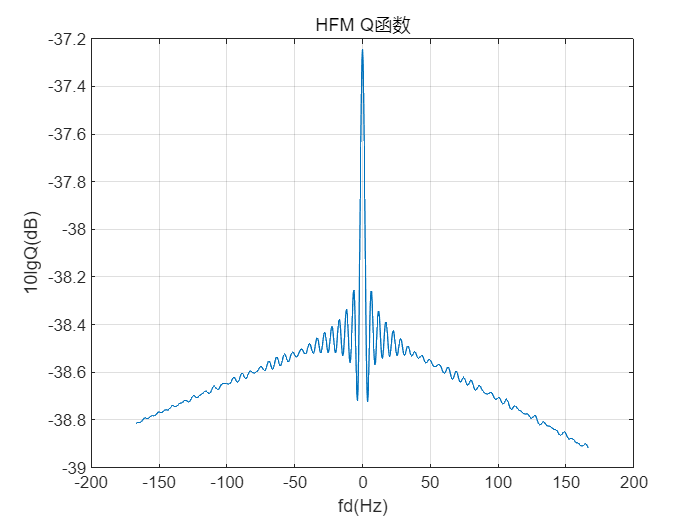

AF_power = abs(AF_norm).^2;
dt = t(2)-t(1);
I1 = sum(AF_power, 2)*dt; 

fd1 = fd;
plot(fd1,10*log10(I1));xlabel('fd(Hz)');ylabel('10lgQ(dB)');grid on;title('HFM Q函数');

clearvars -except I1  fd1         % 只保留 a，其他统统清掉

## M序列

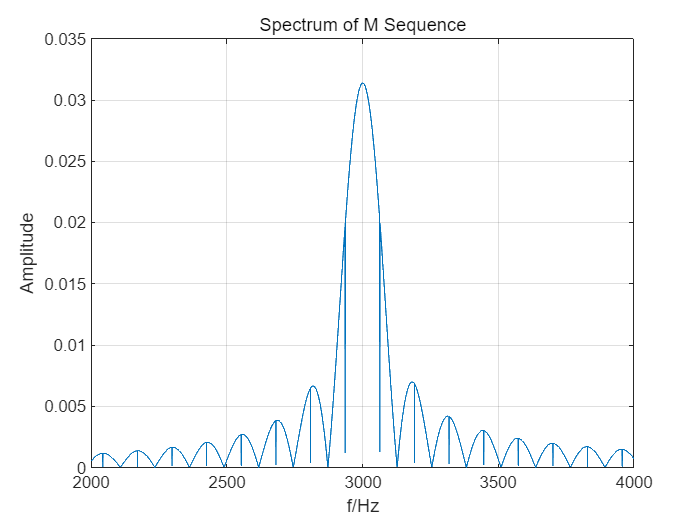

c = 1500;
fs = 24e3;
T = 2;            %脉冲长度
t = 0:1/fs:T-1/fs;

gen_435 = [1 0 0 0 1 1 1 0 1];  % x^8 + x^4 + x^3 + x^2 + 1
init_state = [1 0 1 0 1 0 1 0];  % 8位初始状态，必须非零
M_array = m_seq(gen_435, init_state);
M_array = M_array*2-1;   %0->-1
%M_array = M_array(1:200);  %前200个

t1 = 0:1/fs:T/length(M_array)-1/fs;%每个符号的时间尺度
fc = 3e3;
func = cos(2*pi*fc*t1);
N = length(func);
%window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭
%func = func.*window ;

 
pulse = [];
for i = 1:length(M_array)
    pulse = [ pulse M_array(i)*func];
end

N_fft = length(pulse);
pulse_M_f = fftshift(fft(pulse,N_fft))./N_fft;
freq = (-fs/2:fs/N_fft:fs/2-fs/N_fft);

figure
plot(freq,abs(pulse_M_f));
title('Spectrum of M Sequence');
xlim([2000,4000]);grid on;xlabel('f/Hz');ylabel('Amplitude');


%计算有效相关时宽
Tc = cal_TSP(pulse,fs);

% 计算有效相关带带宽
FSP = cal_FSP(pulse_M_f,N_fft,fs);
fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 1.331667 s
计算有效相关带宽: 190.350802 Hz


时频谱

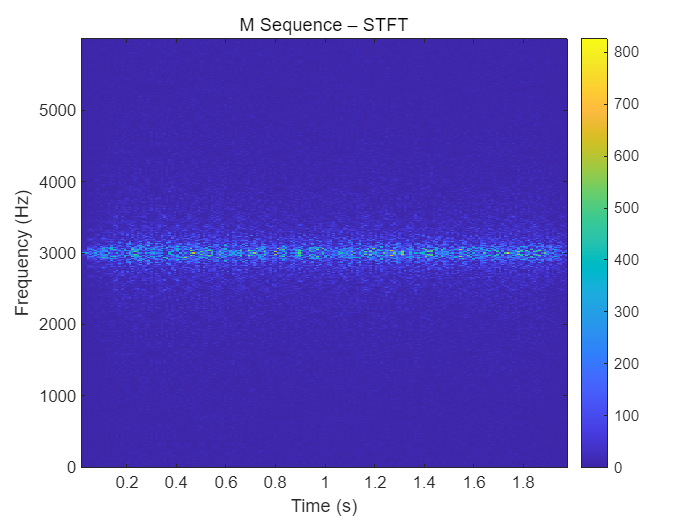


decim = 4;
res_M_seq  = pulse(1:4:end) ;

Nx   = numel(res_M_seq);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh


[tfr_M_seq,~,~] =tfrwv(res_M_seq.', t_idx, Nfft, 0);

fs_res = fs/decim; % 新采样率
tfr_M_seq_shifted = fftshift(tfr_M_seq, 1); % 沿频率轴(第1维)进行fftshift
f_vec_centered = (-Nfft/2:Nfft/2-1)/Nfft*fs_res; % 双边频率向量，以0为中心
t_sec = (t_idx - 1) / fs_res;
f_vec = (0:Nfft-1)/Nfft*fs_res;
figure;
imagesc(t_sec, f_vec, abs(tfr_M_seq_shifted));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('M Sequence – STFT');
colorbar;

M序列模糊函数

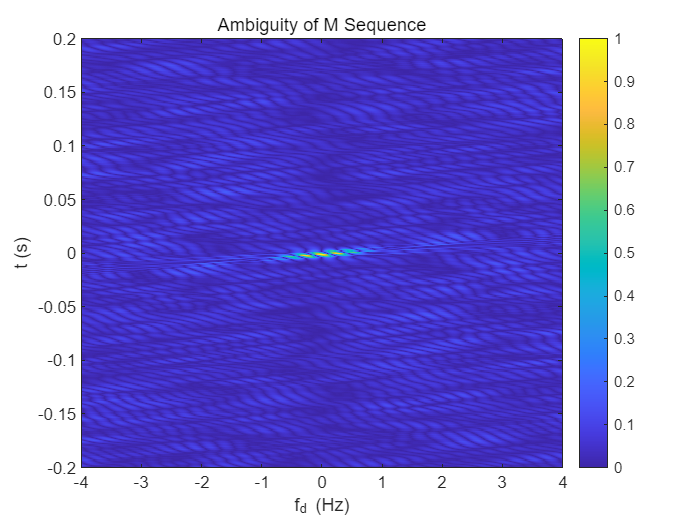

gen_435 = [1 0 0 0 1 1 1 0 1];  % x^8 + x^4 + x^3 + x^2 + 1
init_state = [1 0 1 0 1 0 1 0];  % 8位初始状态，必须非零
M1 = m_seq(gen_435, init_state);

gen_453 = [1 0 0 1 0 1 0 1 1];
M2 = m_seq(gen_453, init_state);

M1 = 2*M1-1;M2 = 2*M2-1;
M1 = M1(1:200);M2 = M2(1:200);

T=0.635;
fs = 1000;
t1 = 0:1/fs:T/length(M1)-1/fs;%每个符号的时间尺度

fc = 500;
func = cos(2*pi*fc*t1);

pulse_M1 = [];pulse_M2 = [];
for i = 1:length(M1)
    pulse_M1 = [ pulse_M1 M1(i)*func];
    pulse_M2 = [ pulse_M2 M2(i)*func];
end


c=1500;

max_velocity = 20;


[Waf, vel_axis,range_axis] = wideband_ambiguity(pulse_M1, pulse_M1, fs, c, max_velocity);
% 绘制距离-多普勒图
figure;
t = range_axis/(c/2);
fd = vel_axis/c*fc;

AF_norm =  Waf./max(max(Waf)).';

imagesc( fd,t,AF_norm );
axis xy tight;
xlabel('f_d (Hz)');
ylabel('t (s)');
title('Ambiguity of M Sequence');
% ylim([-50,50]);
% xlim([-20,20]);
ylim([-0.2,0.2]);
xlim([-4,4]);
colorbar;

Q函数

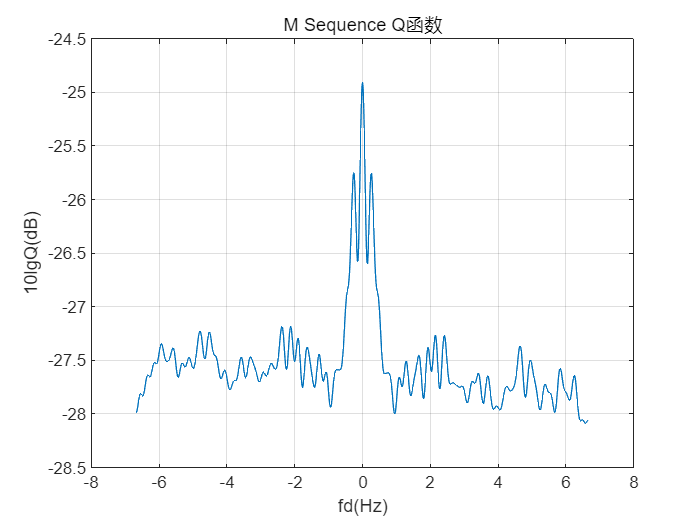

AF_power = abs(AF_norm).^2;
dt = t(2)-t(1);
I2 = sum(AF_power, 1)*dt; 

fd2 = fd;
plot(fd2,10*log10(I2));xlabel('fd(Hz)');ylabel('10lgQ(dB)');grid on;title('M Sequence Q函数');

clearvars -except I1 fd1 I2 fd2           % 只保留 a，其他统统清掉

## Costas序列

T = 2;            %脉冲长度
fs = 12e3;
t = 0:1/fs:T-1/fs;

Costas_array = [1 2 4 8 16 13 7 14 9 18 17 15 11 3 6 12 5 10];%18个符号
Costas_array = Costas_array +ones(1,length(Costas_array));
t1 = 0:1/fs:T/length(Costas_array)-1/fs;   %每个符号的时间尺度
fmin = 2.9e3;   fmax = 3.1e3;fc = 3e3;
delta_freq = (fmax-fmin)/(length(Costas_array)-1);


pulse_costas = [];
for i=1:length(Costas_array)
    pulse_costas = [ pulse_costas  cos(2*pi*( fmin + (Costas_array(i)-1) * delta_freq) * t1) ];
end

#### 频谱

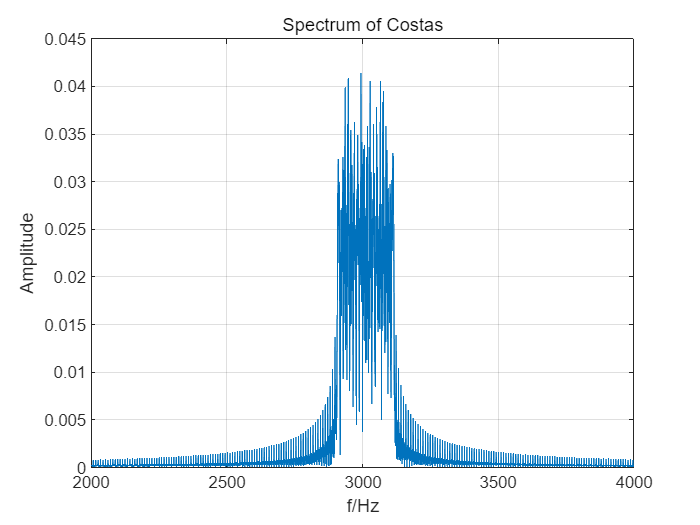

N_fft = length(pulse_costas);
pulse_costas_f = fftshift(fft(pulse_costas,N_fft))./N_fft;
freq = (-fs/2:fs/N_fft:fs/2-fs/N_fft);

figure
plot(freq,abs(pulse_costas_f));
title('Spectrum of Costas');
xlim([2000,4000]);grid on;xlabel('f/Hz');ylabel('Amplitude');

Costas_array = [1 2 4 8 16 13 7 14 9 18 17 15 11 3 6 12 5 10];%18个符号


计算有效相关带宽和有效相关时宽


%计算有效相关时宽
Tc = cal_TSP(pulse_costas,fs);

% 计算有效相关带带宽
FSP = cal_FSP(pulse_costas_f,N_fft,fs);
fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 1.335512 s
计算有效相关带宽: 166.534420 Hz


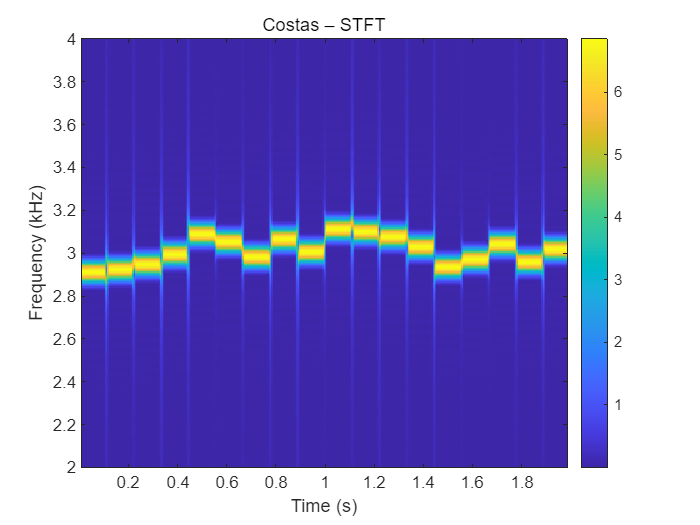



Nx   = numel(pulse_costas);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh

[tfr_Costas,~,~] = tfrstft(pulse_costas.', t_idx, Nfft, win);
figure;
t_sec = (t_idx - 1) / fs;    % ← 自己算，而不是用 t_i
f_vec = (0:Nfft-1)/Nfft*fs;
imagesc(t_sec, f_vec/1e3, abs(tfr_Costas));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
ylim([2,4]);
title('Costas – STFT');
colorbar;

Costas模糊函数

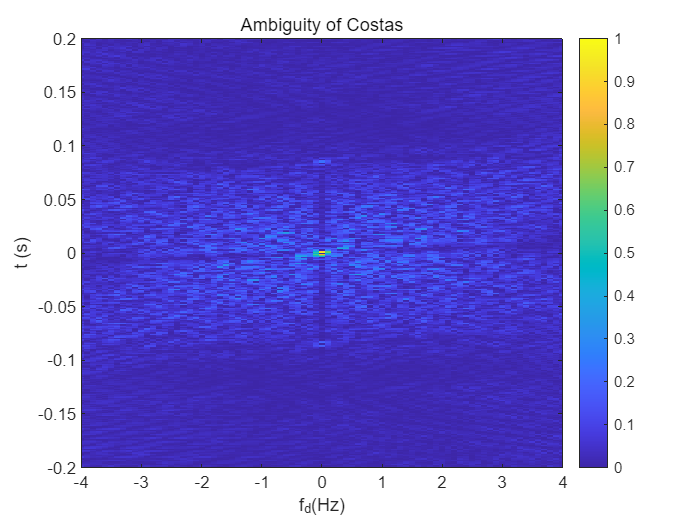

T = 2;            %脉冲长度
t1 = 0:1/fs:T/length(Costas_array)-1/fs;   %每个符号的时间尺度
fmin = 2.9e3;   fmax = 3.1e3;
delta_freq = (fmax-fmin)/(length(Costas_array)-1);
c =1500;
pulse_costas = [];
for i=1:length(Costas_array)
    pulse_costas = [ pulse_costas  cos(2*pi*( fmin + (Costas_array(i)-1) * delta_freq) * t1) ];

end
max_velocity = 20;

[Waf, vel_axis, range_axis] = wideband_ambiguity(pulse_costas, pulse_costas, fs, c, max_velocity);
fd = vel_axis/c*fc;
t = range_axis./(c/2);
AF_norm =  Waf./max(max(Waf));


% 绘制距离-多普勒图
figure;
imagesc(fd, t, AF_norm);
axis xy tight;
xlabel('f_d(Hz)');
ylabel('t (s)');
ylim([-0.2,0.2]);
xlim([-4,4]);
title('Ambiguity of Costas');
colorbar;

Q函数

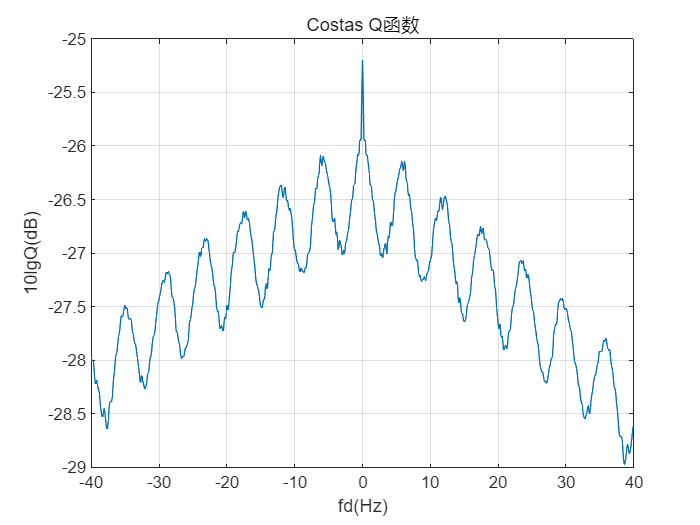

AF_power = abs(AF_norm).^2;
dt = t(2)-t(1);
I3 = sum(AF_power, 1)*dt; 

fd3 = fd;
plot(fd3,10*log10(I3));xlabel('fd(Hz)');ylabel('10lgQ(dB)');grid on;title('Costas Q函数');

Q函数对比

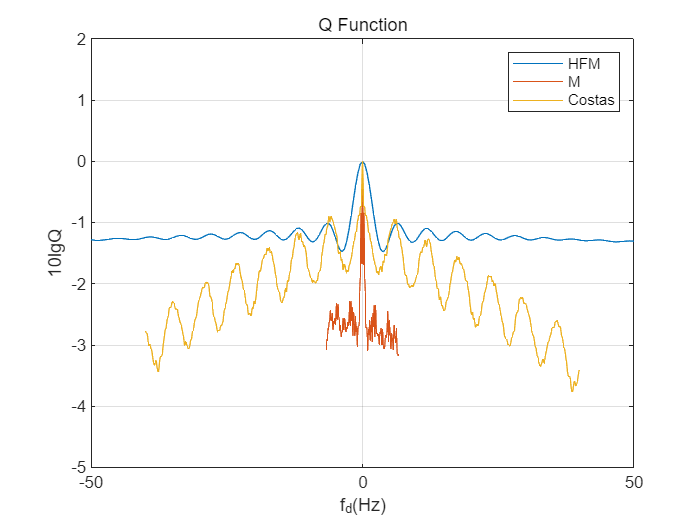

clearvars -except I1 I2 I3  fd1 fd2 fd3      % 只保留 a，其他统统清掉

figure
plot(fd1,10*log10(I1./max(I1)));hold on;
plot(fd2,10*log10(I2./max(I2)));hold on;
plot(fd3,10*log10(I3./max(I3)));hold on; 

legend('HFM','M','Costas');
xlabel('f_d(Hz)');ylabel('10lgQ');title('Q Function');grid on;
ylim([-5,2]);xlim([-50,50]);